# TEMPOmap Foreskin merge_spots

addpath('Z:/Documents/starmap_colab/Code/matlab/');
addpath('Z:/Documents/starmap_colab/Code/matlab/myfunction/');

input_path = 'Z:\Data\Processed\2022-10-15-Rena-SkinCulture254-gene\output\';

## Load TileConfiguration

current_well = '6'

current_well = '6'

rotation_degree = -270;

% merge dots 
stitch_file = fullfile(input_path,  '2022-10-29-rotation\rotated_dapi\', append('Area_', current_well), "TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y', 'z'};
TileConfiguration.x = int32(fix(TileConfiguration.x));
TileConfiguration.y = int32(fix(TileConfiguration.y));
TileConfiguration.z = int32(fix(TileConfiguration.z));

head(TileConfiguration, 5)

ans = 5×4 table
    tile     x       y     z 
    ____    ____    ___    __

    424        0      0     0
    415     1829     -4     0
    406     3662    -10    -1
    397     5492    -20     0
    388     7330    -23    -3



%% Clear temporary variables
clear opts

% Global offsets 
offset_x = abs(min(TileConfiguration.x));
offset_y = abs(min(TileConfiguration.y));
offset_z = abs(min(TileConfiguration.z));

TileConfiguration.x = TileConfiguration.x + offset_x + 1;
TileConfiguration.y = TileConfiguration.y + offset_y + 1;
TileConfiguration.z = TileConfiguration.z + offset_z + 1;

## Merge dots

% load stitched dapi image
dapi_file = fullfile(input_path, "2022-10-30-stitching/dapi/", append('Area', current_well,'.tif'))

dapi_file = "Z:\Data\Processed\2022-10-15-Rena-SkinCulture254-gene\output\2022-10-30-stitching\dapi\Area6.tif"

% dapi_img = imread_big(dapi_file);
dapi_3d = imread_big(dapi_file);
dapi_max = max(dapi_3d, [], 3);

% create empty holders 
merged_points = int32([]);
merged_region = [];

upd = textprogressbar(size(TileConfiguration,1), 'updatestep', 2);

Completed [                    ]   0% --:--:--

for r=1:size(TileConfiguration,1)
% for r=1:3
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y, z] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("Position%03d", tile) 
    curr_dot_file = fullfile(input_path, "2022-10-27-AF546-spot-finding", strcat('AF546_', curr_position_dir, '.mat'));
    if isfile(curr_dot_file)
        load(curr_dot_file); 
        
        %% a twist here: there are position folders that does not contain .mat file
        if ~isempty(centroid)
             if rotation_degree == -90
                % rotate 90 c
                temp = centroid;
                centroid(:, 2) = temp(:, 1);
                centroid(:, 1) = 2049 - temp(:, 2);
             elseif rotation_degree == -180
                % rotate 180 c
                temp = centroid;
                centroid(:, 1) = 2049 - temp(:, 1);
                centroid(:, 2) = 2049 - temp(:, 2);
             elseif rotation_degree == -270
                % rotate 270 c
                temp = centroid;
                centroid(:, 1) = temp(:, 2);
                centroid(:, 2) = 2049 - temp(:, 1);
             end
            
            centroid = int32(centroid) + int32([x y z]);    
            % construct dots region
            current_min = min(centroid, [], 1);
            current_max = max(centroid, [], 1);
            if current_max(1) > size(dapi_max, 2)
                % fprintf("1")
                current_max(1) = size(dapi_max, 2);
                toKeep = centroid(:, 1) <= current_max(1);
                centroid = centroid(toKeep, :);
            
            else if current_max(2) > size(dapi_max, 1)
                    % fprintf("2")
                    current_max(2) = size(dapi_max, 1);   
                    toKeep = centroid(:, 2) <= current_max(2);
                    centroid = centroid(toKeep, :);
                  
            end
            end
            current_region = zeros(size(dapi_max));
            current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
            % current_region(y+1:current_max(2), x+1:current_max(1)) = 1;
            
            % merge dots 
            if isempty(merged_region)
                merged_region = current_region;
            else
                current_overlap = merged_region & current_region;
                merged_region = merged_region | current_region;
                current_region = current_region - current_overlap; 
                
                temp_cell = num2cell(centroid, 2); 
                current_lindex = cellfun(@(x) sub2ind([size(dapi_3d)], x(2), x(1)), temp_cell);
                current_logical = logical(current_region(current_lindex));
                centroid = centroid(current_logical, :);
            end
            
            % save current 
            merged_points = [merged_points; centroid]
        end
    end
    upd(r);
end

curr_position_dir = "Position424"

merged_points = 15×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position415"

merged_points = 34×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [                    ]   2% 00:00:47

curr_position_dir = "Position406"

merged_points = 52×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position397"

merged_points = 76×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=                   ]   5% 00:00:47

curr_position_dir = "Position388"

merged_points = 88×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position379"

merged_points = 118×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=                   ]   8% 00:00:46

curr_position_dir = "Position370"

merged_points = 146×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position361"

merged_points = 146×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [==                  ]  11% 00:00:45

curr_position_dir = "Position425"

merged_points = 166×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position416"

merged_points = 179×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [==                  ]  13% 00:00:44

curr_position_dir = "Position407"

merged_points = 190×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position398"

merged_points = 206×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [===                 ]  16% 00:00:43

curr_position_dir = "Position389"

merged_points = 232×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position380"

merged_points = 269×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [===                 ]  19% 00:00:42

curr_position_dir = "Position371"

merged_points = 294×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position362"

merged_points = 330×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [====                ]  22% 00:00:40

curr_position_dir = "Position426"

merged_points = 349×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position417"

merged_points = 357×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=====               ]  25% 00:00:39

curr_position_dir = "Position408"

merged_points = 371×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position399"

merged_points = 395×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=====               ]  27% 00:00:37

curr_position_dir = "Position390"

merged_points = 416×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position381"

merged_points = 443×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [======              ]  30% 00:00:36

curr_position_dir = "Position372"

merged_points = 470×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position363"

merged_points = 493×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [======              ]  33% 00:00:35

curr_position_dir = "Position427"

merged_points = 530×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position418"

merged_points = 540×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=======             ]  36% 00:00:33

curr_position_dir = "Position409"

merged_points = 552×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position400"

merged_points = 566×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=======             ]  38% 00:00:32

curr_position_dir = "Position391"

merged_points = 582×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position382"

merged_points = 597×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [========            ]  41% 00:00:30

curr_position_dir = "Position373"

merged_points = 623×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position364"

merged_points = 641×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [========            ]  44% 00:00:29

curr_position_dir = "Position428"

merged_points = 666×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position419"

merged_points = 685×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=========           ]  47% 00:00:27

curr_position_dir = "Position410"

merged_points = 688×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position401"

merged_points = 700×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [==========          ]  50% 00:00:26

curr_position_dir = "Position392"

merged_points = 717×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position383"

merged_points = 731×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [==========          ]  52% 00:00:24

curr_position_dir = "Position374"

merged_points = 783×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position365"

merged_points = 792×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [===========         ]  55% 00:00:23

curr_position_dir = "Position429"

merged_points = 809×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position420"

merged_points = 825×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [===========         ]  58% 00:00:22

curr_position_dir = "Position411"

merged_points = 843×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position402"

merged_points = 868×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [============        ]  61% 00:00:20

curr_position_dir = "Position393"

merged_points = 889×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position384"

merged_points = 906×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [============        ]  63% 00:00:19

curr_position_dir = "Position375"

merged_points = 933×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position366"

merged_points = 950×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=============       ]  66% 00:00:17

curr_position_dir = "Position430"

merged_points = 960×3 int32 matrix
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position421"

merged_points = 975×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=============       ]  69% 00:00:16

curr_position_dir = "Position412"

merged_points = 992×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position403"

merged_points = 1013×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [==============      ]  72% 00:00:14

curr_position_dir = "Position394"

merged_points = 1032×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position385"

merged_points = 1051×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [===============     ]  75% 00:00:13

curr_position_dir = "Position376"

merged_points = 1071×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position367"

merged_points = 1088×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [===============     ]  77% 00:00:12

curr_position_dir = "Position431"

merged_points = 1100×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position422"

merged_points = 1108×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [================    ]  80% 00:00:10

curr_position_dir = "Position413"

merged_points = 1128×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position404"

merged_points = 1138×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [================    ]  83% 00:00:09

curr_position_dir = "Position395"

merged_points = 1155×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position386"

merged_points = 1179×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=================   ]  86% 00:00:07

curr_position_dir = "Position377"

merged_points = 1192×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position368"

merged_points = 1203×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=================   ]  88% 00:00:06

curr_position_dir = "Position432"

merged_points = 1226×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position423"

merged_points = 1241×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [==================  ]  91% 00:00:04

curr_position_dir = "Position414"

merged_points = 1253×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position405"

merged_points = 1269×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [==================  ]  94% 00:00:03

curr_position_dir = "Position396"

merged_points = 1280×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position387"

merged_points = 1314×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [=================== ]  97% 00:00:01

curr_position_dir = "Position378"

merged_points = 1332×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


curr_position_dir = "Position369"

merged_points = 1351×3
    690   1635     14
    689   1632     14
    955   1666     15
    939    927     15
     80   1674     16
   2043    719     16
    500   1673     17
    421   1714     18
   1647   1011     18
    462    805     18


Completed [====================] Done. [52 seconds]


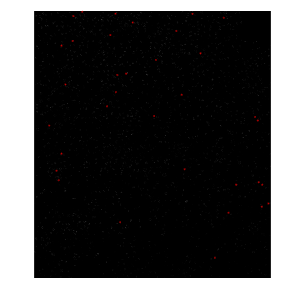


merged_points(:,1) = merged_points(:,1) - 1;
merged_points(:,2) = merged_points(:,2) - 1;
merged_points(:,3) = merged_points(:,3) - 1;

z = 20;
plot_centroids(merged_points(merged_points(:, 3) == z, :), dapi_3d(:,:,z), 1)

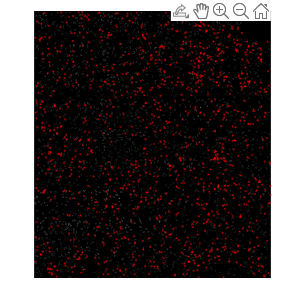


plot_centroids(merged_points, dapi_max, 1)

## output

spot_out_path = fullfile(input_path, '2022-11-07-merged-points', append('Area', current_well));
if ~exist(spot_out_path, 'dir')
    mkdir(spot_out_path)
end
save(fullfile(input_path, '2022-11-07-merged-points', append('Area', current_well), 'merged_AF546_points.mat'), "merged_points");